## Lecture 2 - MATLAB Basics

You can also find this script at [link](https://github.com/smcantab/chen3201-spring2021/tree/main/live_scripts)

### I. Data types

####     Numeric types

    i) **Floating point** (floats)

- Single precision: 32 bits

- Double precision: 64 bits    **(Matlab default)**

format long
double(16.8857365937659375)

ans =   16.885736593765937


single(16.8857365937659375)

ans = single
  16.8857365


       Note that you can change to what precision floats are printed as follows

format long  % print 16 digits
pi

ans =    3.141592653589793


format short % print 5 digits
pi

ans = 3.1416

      ii) **Integers**

- Signed integers (both positive and negative): `int8`, `int16`, `int32`, `int64` (bits)

- Unsigned integers (only positive, double the range as signed int): `uint8`, `uint16`, `uint32`, `uint64` (bits)

int32(-16.8)

ans = int32
-17

% be careful with unsigned integers
uint32(-16.8)

ans = uint32
0

% what happens when you exceed the maximum range of the integers?
int32(10^10)

ans = int32
2147483647

uint32(10^10) % notice how int32 has half the range as uint32

ans = uint32
4294967295

uint64(10^10)

ans = uint64
10000000000

    Note that indices of Vectors and Matrices need to be integers, the canNOT be floats.

####     Characters and strings

- A **character** array is a sequence of characters, just as a numeric array is a sequence of numbers. A typical use is to store short pieces of text as ***character vectors***, such as `c = 'Hello World'`.

A = 'Four score and seven years ago'

A = 'Four score and seven years ago'

A(1)

ans = 'F'

- A string array is a container for pieces of text. String arrays provide a set of functions for working with text as data. Starting in R2017a, you can create strings using double quotes, such as `str = "Greetings friend"`. To convert data to string arrays, use the [`string`](https://www.mathworks.com/help/matlab/ref/string.html) function. **Unlike characters, a string is not a primitive data type.**

str = string(A)

str = "Four score and seven years ago"

str(1)

ans = "Four score and seven years ago"

####    Booleans (logical)

- `true` (1) and f`alse` (0)

1 == 2 % is 1 equal to 2? False

ans = logical
   0


1 == 1 % is 1 equal to 1? True

ans = logical
   1


### II. Data structures

####     Scalars

x = 10.3

x = 10.3000

    Useful MATLAB functions:

- `abs(x)`                 absolute value of x

abs(-10)

ans = 10

- `mod(x, y)      remainder of x/y`

mod(10, 3)

ans = 1

- `round(x)       `the `round` function rounds away from zero to the integer with larger magnitude.

- `floor(x)       `rounds down

- `ceil(x)        `rounds up

% negative numbers
x = -1.6;    %`;` suppresses the output in matlab
round(x)

ans = -2

floor(x)

ans = -2

ceil(x)

ans = -1

% positive numbers
x = 1.6;    %`;` suppresses the output in matlab
round(x)

ans = 2

floor(x)

ans = 1

ceil(x)

ans = 2

- `real(x)        `real part of imaginary number

- `imag(x)        `imaginary part of complex number

x = 1 + 2i;
real(x)

ans = 1

imag(x)

ans = 2

- `exp(x)         e^x`

- `cos(x)         `cosine in radians

- `acos(x)        `inverse cosine in radians

x = 1.6;
exp(x)

ans = 4.9530

cos(x)

ans = -0.0292

acos(x)

ans = 0.0000 + 1.0470i

####     Vectors (1D Matrices)

    **Row vector**

x = [5.1 2.6 1.1]   % space separated

x =     5.1000    2.6000    1.1000


x = [5.1, 2.6, 1.1] % comma separated

x =     5.1000    2.6000    1.1000


**    Column Vector**

x = [5.1; 2.6; 1.1]

x =     5.1000
    2.6000
    1.1000


To access an element of the vector just do (indexing in MATLAB starts from 1 not zero! Be careful it is easy to be off by 1 in MATLAB!)

x = [5.1; 2.6; 1.1; 4.7; 9.3]

x =     5.1000
    2.6000
    1.1000
    4.7000
    9.3000


x(1)            % get first element of the vector

ans = 5.1000

x(1:3)          % get elements 1 through 3

ans =     5.1000
    2.6000
    1.1000


x(1:2:end)      % get every second element

ans =     5.1000
    1.1000
    9.3000


x(1:3:end)      % get every 3rd element

ans =     5.1000
    4.7000


x(end:-1:1)     % reverse vector

ans =     9.3000
    4.7000
    1.1000
    2.6000
    5.1000


x([2 3]) = 1    % replace 2nd and 3rd element with 1

x =     5.1000
    1.0000
    1.0000
    4.7000
    9.3000


x([5, 4, 3, 2, 1])

ans =     9.3000
    4.7000
    1.0000
    1.0000
    5.1000


     For more examples of matrix/vector indexing see [link](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html)

    If you want to **concatenate** two vectors you can do

a = [1 2];
b = [3 4];
[a, b]      % concatenate in rows

ans =      1     2     3     4


[a; b]      % concatenate in column

ans =      1     2
     3     4


a = [1; 2];
b = [3; 4];
[a, b]      % concatenate in rows

ans =      1     3
     2     4


[a; b]      % concatenate in column

ans =      1
     2
     3
     4


You can generate a vector of integers as follows

x = [0:99]      % generate a vector of integers 0 through 99 (length 100)

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x = [0:2:99]    % generate a vector of integers 0 through 99 every 2 (length 50)

x =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


**    Linspace and Logspace**

    `Linspace` takes as arguments `(initial value, final value, number of increments)` so that


$$\text{increment} = \frac{\text{final value} - \text{initial value}}{n-1}$$


    For instance if we use the parameters `(0, 1, 5)` we will find


$$\text{increment} = \frac{1-0}{5-1}=1/4=0.25$$


x = linspace(0, 1, 5)

x =          0    0.2500    0.5000    0.7500    1.0000


    Linspace can also iterate backwards

x = linspace(10, -1, 12)

x =     10     9     8     7     6     5     4     3     2     1     0    -1


    If you want to get the length of a vector do

length(x)

ans = 12

    Similarly `logspace(a, b, n)` generates `n` points between the decades `10^a` and `10^b`

logspace(-1, 2, 4)

ans =     0.1000    1.0000   10.0000  100.0000


####     Matrices

A = [1 3 2; 2 1 3; 1 4 1]       % space separated

A =      1     3     2
     2     1     3
     1     4     1


A = [1, 3, 2; 2, 1, 3; 1, 4, 1] % comma separated

A =      1     3     2
     2     1     3
     1     4     1


    If you want to get the size/shape of a matrix do

size(A)

ans =      3     3


    I recommend that you always initialize a vector or a matrix before populating it. This is not just faster, but it is also in line with every other general purpose computer language, so it is a good habit to have. You can initialize matrices as follows

b = zeros(1, 3)     % make a 1x3 matrix (row vector) of zeros

b =      0     0     0


A = zeros(3, 2)     % make a 3x2 matrix of zeros

A =      0     0
     0     0
     0     0


C = eye(3, 3)       % make a 3x3 matrix of zeros with ones along the diagonal

C =      1     0     0
     0     1     0
     0     0     1


C = eye(3, 2)       % make a 3x2 matrix of zeros with ones along the diagonal

C =      1     0
     0     1
     0     0


 You can access a specific entry of the matrix by specifying the indeces `A(n_row, n_columns)`

A = [1 3 2; 2 1 3; 1 4 1]

A =      1     3     2
     2     1     3
     1     4     1


A(3, 2)             % should be 4

ans = 4

A(3, :)             % extract whole 3rd row

ans =      1     4     1


A(:, 2)             % extract whole 2nd column

ans =      3
     1
     4


A(1:2, :)           % extract all columns from first 2 rows

ans =      1     3     2
     2     1     3


A(:, 1:2)           % extract all rows from first 2 columns

ans =      1     3
     2     1
     1     4


A(1:2:3, :)         % extract all columns every 2nd row

ans =      1     3     2
     1     4     1


A(:, 1:2:3)         % extract all rows every 2nd column

ans =      1     2
     2     3
     1     1


A([1 1], [2 3]) = 0 % replace positions (1, 2) and (1, 3) with zeros

A =      1     0     0
     2     1     3
     1     4     1


To transpose a matrix or a vector is `.'` while the complex conjugate transpose is `'`

b.'         % vector transpose

ans =      0
     0
     0


C = C + 1i

C =    1.0000 + 1.0000i   0.0000 + 1.0000i
   0.0000 + 1.0000i   1.0000 + 1.0000i
   0.0000 + 1.0000i   0.0000 + 1.0000i


C.'         % matrix transpose

ans =    1.0000 + 1.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i
   0.0000 + 1.0000i   1.0000 + 1.0000i   0.0000 + 1.0000i


C'          % complex conjugate transpose

ans =    1.0000 - 1.0000i   0.0000 - 1.0000i   0.0000 - 1.0000i
   0.0000 - 1.0000i   1.0000 - 1.0000i   0.0000 - 1.0000i


    Matrix/vector multiplication is as simple as

x = [1 2 3];
y = [3; 2; 1];
x*y             % 1*3 + 2*2 + 1*3 -> 10

ans = 10

   For **element-wise** multiplication simply do

x.*y'            % [1*3 2*2 3*1] -> [3 4 3]

ans =      3     4     3


x.*y             % [1*3 2*3 3*3; 1*2 2*2 3*2; 1*1 2*2 3*1]  

ans =      3     6     9
     2     4     6
     1     2     3


For element-wise power do `.^` while for matrix power fo `^ `(matrix must be square for matrix power)

A = [1 2; 3 4];
A.^2            % Aij^2

ans =      1     4
     9    16


A^2             % A*A

ans =      7    10
    15    22


###     III. Operator precedence (order of operations)

- Brackets `()`

- Transpose `(.')`, power `(.^)`, complex conjugate transpose `(')`, matrix power `(^)`

- Multiplication `(.*)`, right division `(./)`, matrix multiplication `(*)`, matrix right division `(/)`

- Addition `(+)`, subtraction `(-)`

- Less than `(<)`, less than or equal to `(<=)`, greater than `(>)`, greater than or equal to `(>=)`, equal to `(==)`, not equal to `(~=)`

`See `[link](https://www.mathworks.com/help/matlab/matlab_prog/operator-precedence.html) for a complete list of rules

-5*3^2-10*(4-2) % do (); do .^; do *; do .-

ans = -65

###     IV. Relational operators

-     `==`        Equal to

-     `~=`        Not equal to (most other languages do this using `!=`)

-     `>`          Greater than

-     `>=`        Greater than or equal to

-     `<`           Less than

-     `<=`         Less than or equal to

A = linspace(1, 9, 9)

A =      1     2     3     4     5     6     7     8     9


B = linspace(9, 1, 9)

B =      9     8     7     6     5     4     3     2     1


A>B

ans = 1×9 logical array
   0   0   0   0   0   1   1   1   1


###     V. Logical operations

    The `logical` data type represents `true` or `false` states using the numbers `1` and `0`, respectively. Certain **functions** and **operators return logical values to indicate fulfillment of a condition**.

- `& `                       Logical AND

- `~  `                     Logical NOT

- `|`                         Logical OR

- `&&, ||`               Short-circuit AND and OR (they operate only on scalars) e.g. `expr1 && expr2 ->` `expr2` not evaluated if `expr1` is evaluated to `false` (logical `0`)

- `xor(A, B) `      Logical exclusive-OR (logical statements A or B are true but **not** **both**

- `all(x)       `Determine if **all** elements of `x` are` 0 `or` true`

- `any(x)       `Determine if **any** elements of `x` are` 0 `or` true`

A = linspace(1, 9, 9)

A =      1     2     3     4     5     6     7     8     9


(A > 2) & (A < 6)           % element-wise AND

ans = 1×9 logical array
   0   0   1   1   1   0   0   0   0


3 > 2 && 3 < 1 && 3 > 1     % short-circuting, returns false

ans = logical
   0


3 > 2 & 3 < 1 & 3 > 1       % without s.c., returns false

ans = logical
   0


See [link](https://www.mathworks.com/help/matlab/logical-operations.html?searchHighlight=logical%20operators&s_tid=srchtitle) for a complete list of logical operators and functions.

###     VI. I/O

####     Input

     i) Type in by hand

A = [1, 5, 3; 2, 1, 7; 1, 2, 8]

A =      1     5     3
     2     1     7
     1     2     8


    ii) Prompt user

%x = input('Enter x value')

    iii) Read from file

x = load('testfile.m')

x = 2

####     Output

    i) Display

disp('something to display')

x =      1     2     3
     4     5     6
     7     8     9


    ii) Formatted output (see [link](https://www.mathworks.com/help/simulink/slref/fprintf.html) for full documentation)

-     `fprintf(text)`

-     `\n     `new line

-     `\t     `tab

-      `%5d   ` signed integer with field width 5

-     %6.2f      float with field total width 6 and 2 decimal places

x = 123456.7891

something to display


fprintf('x = %10.5f \n', x)
fprintf('x = %15.5f \n', x)

###     VII. Plotting

x = [0:100] / 200;

x = 1.2346e+05

y = sin(2*x*pi);

x = 123456.78910 


y2 = sin(4*x*pi);

x =    123456.78910 


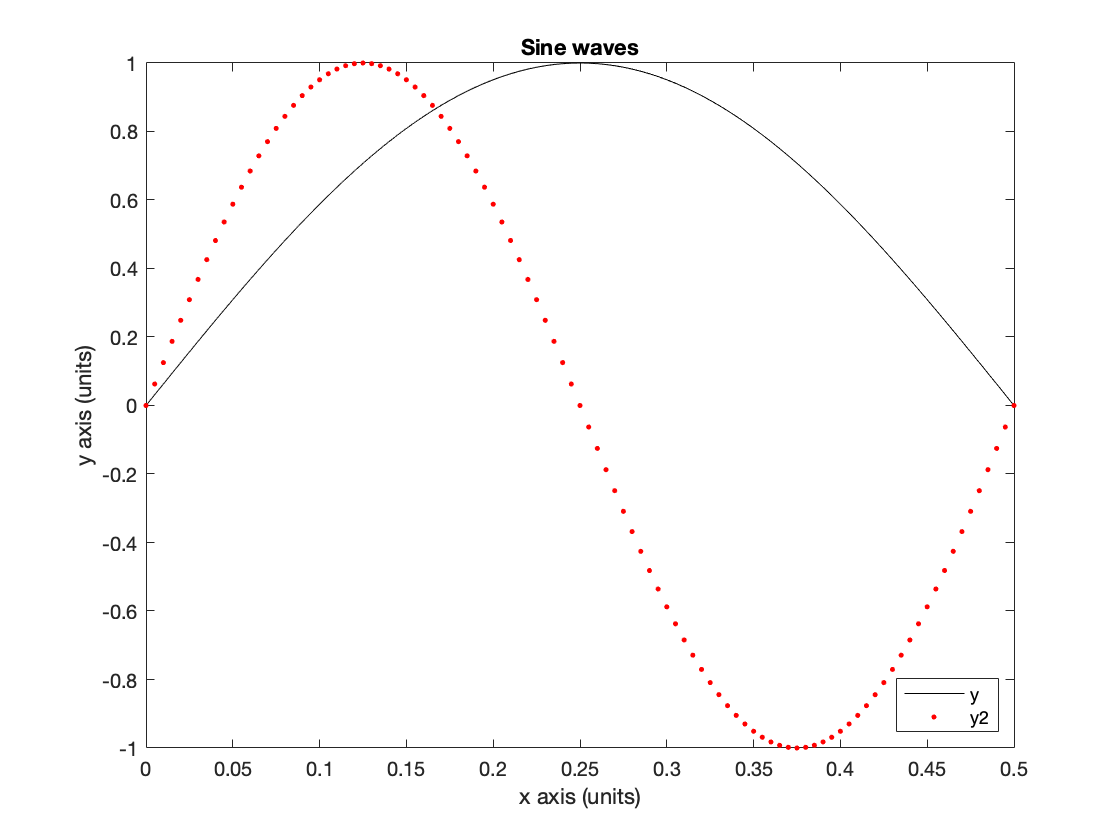


h = figure(1);              % create a figure
plot(x, y, '-k')            % `-` means `line` and `k` means `black`
hold on                     % continue adding to the same plot
plot(x, y2, '.r')           % `.` means `dots` and `r` means `red`
hold off                    % stop holding
xlabel('x axis (units)')    % set x-axis label
ylabel('y axis (units)')    % set y-axis label
title('Sine waves')         % set title
legend('y', 'y2', 'Location', 'southeast'); % set legend
saveas(h, 'fig1.png');      % save to png file

See [link](https://www.mathworks.com/help/matlab/ref/plot.html?searchHighlight=plot&s_tid=srchtitle) for full documentation on `plot`